# 雷达信号处理算法：静态杂波滤除

本期文章将介绍三种雷达信号处理常用的静态杂波滤方法的基本原理，分别是零速通道置零法、动目标显示（MTI）以及相量均值相消算法（平均相消算法），并分析了静态杂波的滤除效果，以及三种方法的优缺点和应用场景，最后提供了一个MATLAB程序和数据以供读者学习参考。

数据说明：本文所采用的数据为雷达采集室内人员目标运动的一帧数据，采用的硬件平台为IWR1642，其中数据是通过串口直接输出，由MATLAB接收并处理。相关的操作和下面的链接中的操作是近似的，只是本文仅对静态杂波滤除算法做分析。

## 零速通道置零法

零速通道置零法，是指在2D-FFT（速度维FFT）后直接将R-V谱矩阵（RD图）速度通道中的零速通道或零速附近通道置零，此操作意味着静止目标或者低速目标会直接从R-V谱矩阵中消失。零速通道置零法操作简单，易于理解。

零速通道置零法，是指在2D-FFT（速度维FFT）后直接将R-V谱矩阵（RD图）速度通道中的零速通道或零速附近通道置零，此操作意味着静止目标或者低速目标会直接从R-V谱矩阵中消失。零速通道置零法操作简单，易于理解。

如图1所示，是未经过任何处理的R-V谱矩阵，其中室内人员目标在3.5米左右，速度为-0.317m/s，靠近雷达运动。

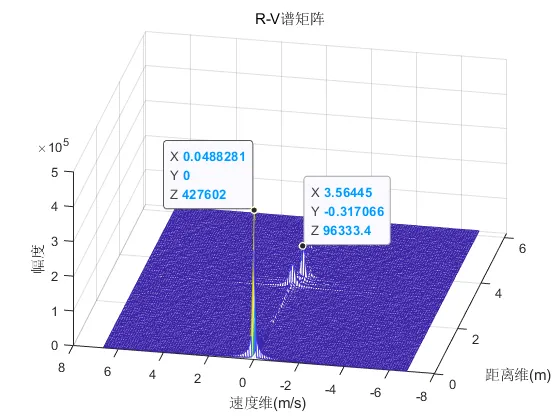

图1 R-V谱矩阵（未经过静态杂波滤除）

图1中信号的直流分量幅值很高，目标的幅度被直流分量严重压制，在进行后续的CFAR处理之前最好能够将信号的直流分量去除，便于提高雷达的性能。图2所示是零通道置零法的效果，其中本程序对零速通道以及零速通道相邻的一个通道都置为零。零速通道置零法对目标的幅度没有发生改变，对直流分量有一定的抑制效果，但对目标的微多普勒信息有一定的损失。因此，采用这种最简单的方法需要考虑具体的应用场景。

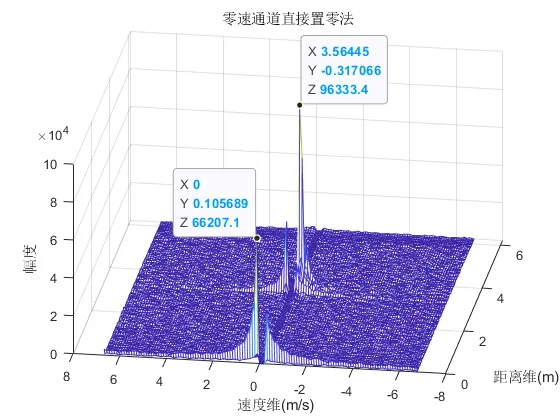

图2 零速通道置零法

微多普勒信息，对于不同的雷达具有不同的作用。例如，对于室内人员检测雷达，则微多普勒信息就显得非常重要，因为人体目标是非刚体物体，其身体各个部分的运动会带来许多的微多普勒效应，因此保留这部分信息对于后续的信号处理或者数据处理都具有非常重要的意义。对于高速目标，如交通流量检测雷达，微多普勒信息就显得不那么重要 ，因为汽车运动的速度是非常快的。关于雷达微多普勒的效应，更多内容可以阅读Victor C. Chen的《雷达中的微多普勒效应》一书，需要本书可私信调皮哥。

## 2.动目标显示（MTI）

MTI是雷达工程师们熟稔于心的雷达信号处理算法，基本上没有不了解的。MTI是指利用杂波抑制滤波器来抑制杂波，提高雷达信号的信杂比，以利于运动目标检测的技术。由于杂波谱通常集中在直流分量和雷达重复频率的整数倍处，而 MTI 滤波器利用杂波与运动目标的多普勒频率的差异，使得滤波器的频率响应在直流和PRF（脉冲重复频率） 的整数倍处具有较深的阻带， 而在其他频点的抑制较弱， 从而通过较深的“凹口”抑制静止目标和静物杂波。在实验中，通常采用两脉冲对消器，也称一次对消器,其滤波器结构如下图3所示。

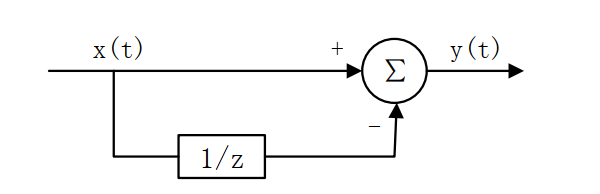

图 3 一次对消滤波器结构图

一次对消器的时域表达式和传递函数如下：


$$\begin{array}{c}y(n)=x(n)-x(n-1)\\ H(z)=1-z^{-1}\end{array}$$


MTI的核心原理就是静止目标的相位不会发生变化，而运动目标的相位与静止目标不同，因此相邻两个脉冲做差会把相同的相位值减掉，留下的就是运动目标的相位，从而达到滤除静止目标的功能。

MTI的效果如图4所示，其中信号的直流分量部分得到了良好的抑制，但同时目标的幅值也受到了同样的影响，因为在一次对消过程中，相邻的脉冲相减其实除了相位得到了消除，还有“复数绝对值”的削弱。另外，MTI由于仅对零速通道附近的信号“陷波”，而对于高速通道保持不变，因此得到图4的结果中背景噪声显得非常杂乱。

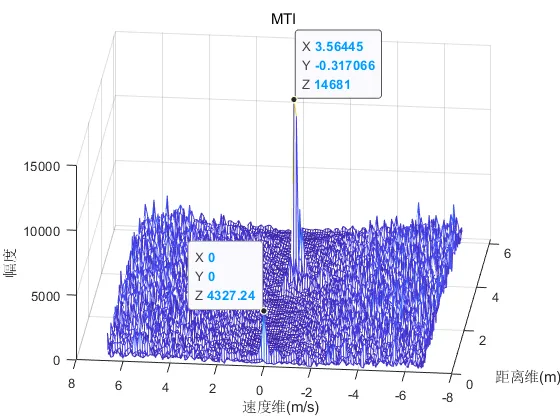

图4 MTI一次对消效果

## 3.相量均值相消算法（平均相消算法）

相量均值相消算法，也被称为平均相消算法，其实现的原理为：静止目标到雷达天线的距离是不变的，每一束接收脉冲上静止目标的时延也是不变的，对所有接收脉冲求平均就可以得到参考的接收脉冲，然后用每一束接收脉冲减去参考接收脉冲就可以得到目标回波信号，核心思想是求均值做差。

其实现的过程为：首先对所有接收脉冲求平均得出参考接收脉冲，接着利用每一束接收脉冲减去参考接收脉冲就可以得到目标回波信号，参考接收脉冲的表达式为：


$$C[m]=\frac{1}{N}\sum_{i=1}^N R[m,i]
$$


其中，m为快时间维（距离维）采样点，i为慢时间维（速度维）时间采样点，相量均值相消算法的公式为：�

R[m,n]=R[m,n]-C[m]

相量均值相消的算法原理模型如图5所示，倘若目标为静止目标，则chirp回波信号的相位相同，相量求和后累加得到的均值会很大，如 (n1+n2+n3)/3 ，则每个chirp信号减完均值之后信号幅度变得非常小。假设目标是运动目标或者微动目标，由于目标运动会导致每个调频脉冲信号间的相位不同，其相量求和累加后会出现抵消，则其均值会很小，如 (m1+m2+m3)/3 ，每个chirp信号减完均值后幅值影响不大。因此，运动或微动的目标就会在速度维傅里叶变换后变得“突出”。

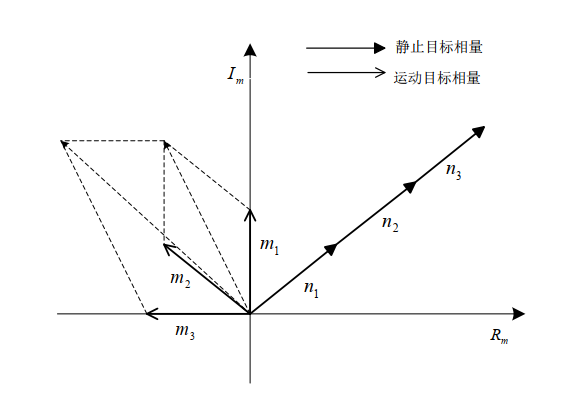

图5 相量均值相消算法模型

综上所述，MTI和相量均值相消算法两种算法在原理的核心思想上有些许近似，最大的区别为：MTI是直接利用相位的差值消除静态杂波，而相量均值相消算法是通过相量叠加再求平均然后做差，去除静态杂波。因此MTI仅仅是抑制了静态目标的相位，对于微动目标不友好。而相量均值相消算法则通过求均值，在抑制静止目标相位的同时极大提高了动目标或者微动目标的信噪比。

如图6所示，是相量均值相消算法的效果，信号的直流分量得到了一定程度的抑制，但整体抑制效果没有MTI那么明显。相量均值相消算法最优的特点是对目标的幅度没有削弱作用，但其背景噪声比较干净，同时对微多普勒的信息保留的比较完整，完全让目标保持了较高的信噪比。

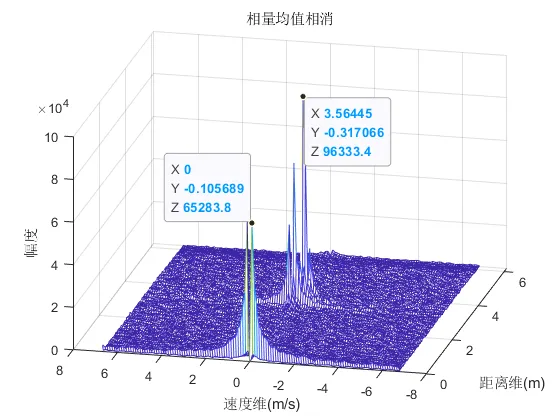

图6 相量均值相消算法效果

对于人员目标的检测，建议采用这种算法。如图7所示，是相量均值相消算法并去除了直流分量后的效果，基本上可以达到非常理想的效果。

## 4.MATLAB代码

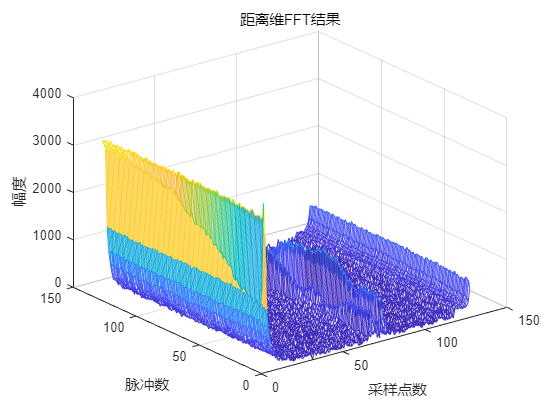


%% 作者：调皮连续波
%% 公众号：调皮的连续波
%% 时间2022年04月
%%
clc;
close all;
clear all;

%% 雷达参数
Tx_Number = 2;               %发射天线
Rx_Number = 4;               %接收天线
Range_Number = 128;          %距离点数（每个chirp 128个点）
Doppler_Number = 128;         %多普勒通道数
global Params;
Params.NChirp = Doppler_Number;               %1帧数据的chirp个数
Params.NChan =  Rx_Number;                    %RxAn数,ADC通道数
Params.NSample = Range_Number;                %每个chirp ADC采样数
Params.Fs = 2.5e6;                          %采样频率
Params.c = 3.0e8;                     %光速
Params.startFreq = 77e9;              %起始频率 
Params.freqSlope = 60e12;             %chirp的斜率
Params.bandwidth = 3.072e9;           %真实带宽
Params.lambda=Params.c/Params.startFreq;    %雷达信号波长
Params.Tc = 144e-6;                         %chirp周期
global FFT2_mag;

%% 坐标计算
[X,Y] = meshgrid(Params.c*(0:Params.NSample-1)*Params.Fs/2/Params.freqSlope/Params.NSample, ...
    (-Params.NChirp/2:Params.NChirp/2 - 1)*Params.lambda/Params.Tc/Params.NChirp/2);   
       
adc_data =load('angle_15.mat');
Data_dec=(adc_data.prompt_1);  %将16进制转换为10进制

%% 数据读取、拆分、组合
Data_zuhe=zeros(1,Tx_Number*Rx_Number*Doppler_Number*Range_Number*2); %建立计算存储数据的空矩阵
for i=1:1:Tx_Number*Rx_Number*Doppler_Number*Range_Number*2
    
    Data_zuhe(i) = Data_dec((i-1)*2+1)+Data_dec((i-1)*2+2)*256;%两个字节组成一个数，第二个字节乘以256相当于左移8位。
    if(Data_zuhe(i)>32767)
        Data_zuhe(i) = Data_zuhe(i) - 65536;  %限制幅度
    end
end

%% 分放数据
ADC_Data=zeros(Tx_Number,Doppler_Number,Rx_Number,Range_Number*2); %建立计算存储数据的空矩阵
for t=1:1:Tx_Number
    for i=1:1:Doppler_Number
        for j=1:1:Rx_Number
            for k=1:1:Range_Number*2 %实部虚部
                ADC_Data(t,i,j,k) = Data_zuhe(1,(((t-1)*Doppler_Number+(i-1))*Rx_Number+(j-1))*Range_Number*2+k);%时域数据排列顺序为 TX1 TX2
            end
        end
    end
end

%% 打印全部的实虚数据
Re_Data_All=zeros(1,Range_Number*Doppler_Number*Tx_Number*Rx_Number); %建立计算存储数据的空矩阵
Im_Data_All=zeros(1,Range_Number*Doppler_Number*Tx_Number*Rx_Number); %建立计算存储数据的空矩阵

% 虚部实部分解
for i=1:1:Tx_Number*Rx_Number*Doppler_Number*Range_Number
    Im_Data_All(1,i) = Data_zuhe(1,(i-1)*2+1);
    Re_Data_All(1,i) = Data_zuhe(1,(i-1)*2+2);
end

% 原始信号实部、虚部图形绘制 
% figure()
% subplot(2,1,1);
% plot(Im_Data_All(1,1:3000));title('实部波形');
% xlabel('采样点数');
% ylabel('幅度');
% subplot(2,1,2);
% plot(Re_Data_All(1,1:3000),'r');title('虚部波形');
% xlabel('采样点数');
% ylabel('幅度');

%% 打印分组后的实虚数据 数据结构为：2T4R在TX2组的16个脉冲数据
Re_Data=zeros(Doppler_Number,Range_Number); %建立计算存储数据的空矩阵
Im_Data=zeros(Doppler_Number,Range_Number); %建立计算存储数据的空矩阵

for chirp=1:Doppler_Number %查看所在chirp的数据 
for j=1:1:Tx_Number
    for k=1:1:Rx_Number
        for i=1:1:Range_Number
            Re_Data(chirp,i) = ADC_Data(j,chirp,k,(i-1)*2+2);
            Im_Data(chirp,i) = ADC_Data(j,chirp,k,(i-1)*2+1);
        end
    end 
end
end

%% 虚部+实部数据重组得到复信号 
ReIm_Data = complex(Re_Data,Im_Data); %这里只用虚拟天线的最后一组数据。原本数据大小应该是16*256*8=32768，现在只有16*256*1=4096。
ReIm_Data_All =complex(Re_Data_All,Im_Data_All);

ReIm_Data_all1 = zeros(Range_Number,Doppler_Number,4);
ReIm_Data_all2 = zeros(Range_Number,Doppler_Number,4);

%% 虚拟阵列重组 4通道->8通道
for nn=1:4
    for mm=1:Range_Number       
            ReIm_Data_all1(mm,:,nn) = ReIm_Data_All((nn-1)*Range_Number+ ((mm-1)*4*Range_Number+1):((mm-1)*4*Range_Number+Range_Number)+(nn-1)*Range_Number  );          
            ReIm_Data_all2(mm,:,nn) = ReIm_Data_All((nn-1)*Range_Number+131072/2+((mm-1)*4*Range_Number+1):131072/2+((mm-1)*4*Range_Number+Range_Number) +(nn-1)*Range_Number );
    end
end

ReIm_Data_All = cat(3,ReIm_Data_all1(:,:,1:4), ReIm_Data_all2(:,:,1:4));

%% 1D FFT
fft1d= zeros(Doppler_Number,Range_Number,8);
for qq =1:8
    for chirp_fft=1:Doppler_Number 
        fft1d(chirp_fft,:,qq) = fft((ReIm_Data_All(chirp_fft,:,qq)));
    end
end

FFT1_mag=abs(fft1d(:,:,1));
figure(1);
mesh(FFT1_mag);
xlabel('采样点数');ylabel('脉冲数');zlabel('幅度');
title('距离维FFT结果');

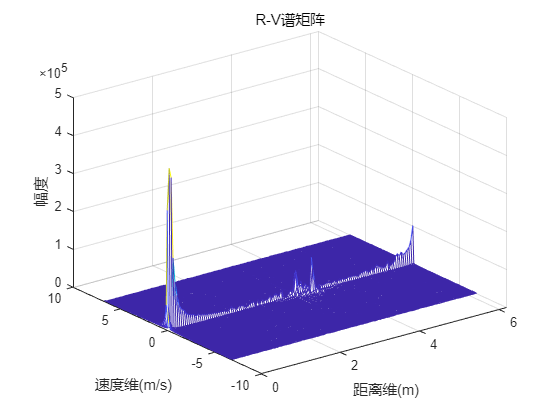


%%  MTI 动目标显示
fft1d_MTI= zeros(Range_Number,Doppler_Number,8);
for cc =1:8
    for ii =1:Doppler_Number-1
        fft1d_MTI (ii,:,cc) = fft1d(ii+1,:,cc)-fft1d(ii,:,cc);
    end
end
% 
% 
% mesh(abs(ReIm_Data_All(:,:,1)));

%%  相量均值相消算法-静态杂波滤除
fft1d_avg = zeros(128,128,8);
for n=1:8
    avg = sum(fft1d(:,:,n))/128;

    for chirp=1:128
        fft1d_avg(chirp,:,n) = fft1d(chirp,:,n)-avg;
    end
end

% figure;
% mesh(X,Y,abs(fft1d_jingtai(:,:,1)));
% fft1d =fft1d_jingtai;
%%

%% 2D FFT 

fft2d= zeros(Doppler_Number,Range_Number,8);
for kk=1:8
    for chirp_fft=1:Range_Number 
        fft2d(:,chirp_fft,kk)     =fftshift( fft((fft1d(:,chirp_fft,kk)))); %未经过静态杂波滤除
        fft2d_MTI(:,chirp_fft,kk) =fftshift( fft((fft1d_MTI(:,chirp_fft,kk)))); %MTI
        fft2d_avg(:,chirp_fft,kk) =fftshift( fft((fft1d_avg(:,chirp_fft,kk)))); %相量均值法
    end
end

figure(2);
fft2d_0 =abs(fft2d(:,:,1));
mesh(X,Y,fft2d_0);
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('R-V谱矩阵');

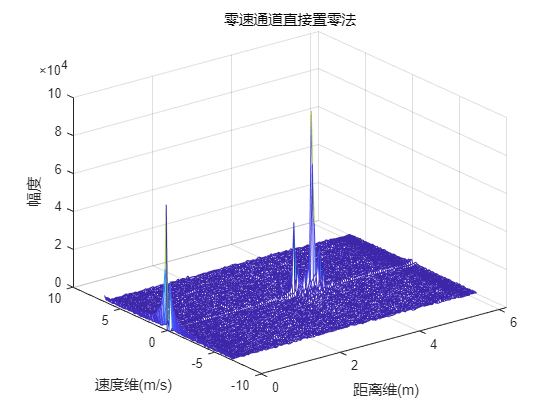


figure(3);
fft2d_0 =abs(fft2d(:,:,1));
fft2d_0(63:65,:)=0;
mesh(X,Y,fft2d_0);
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('零速通道直接置零法');

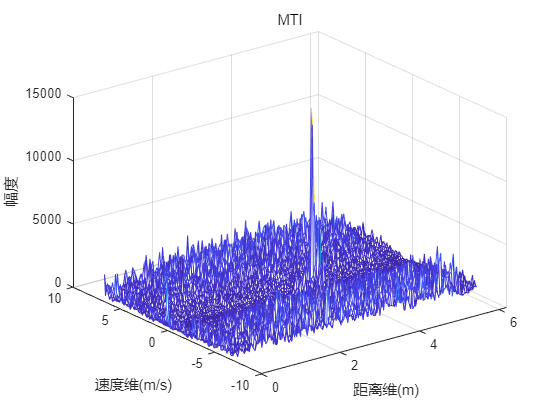



figure(4);
mesh(X,Y,abs(fft2d_MTI(:,:,1)));
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('MTI');

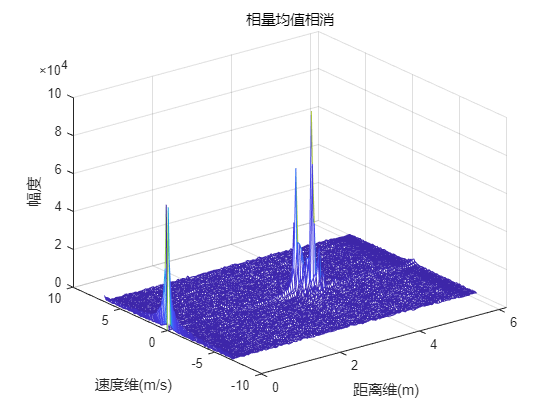


figure(5);
mesh(X,Y,abs(fft2d_avg(:,:,1)));
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('相量均值相消');

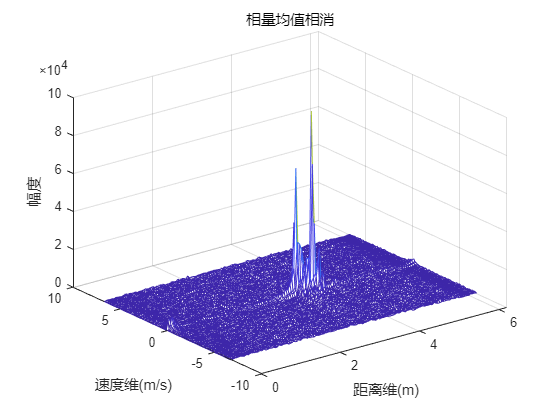


%直流分量去除 相量均值相消算法-静态杂波滤除
figure(6)
fft2d_avg(:,1,1) =0;
mesh(X,Y,abs(fft2d_avg(:,:,1)));
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('相量均值相消');

# 雷达信号处理：直流分量去除

[干货 | 雷达信号处理之直流分量去除 (qq.com)](https://mp.weixin.qq.com/s?__biz=MzkxMTMwMTg4Mg==&mid=2247484505&idx=1&sn=6c695ecc89838153f55fed2a67d2cf24&chksm=c11f09ccf66880dad9eab2fbdf10d6942e7315487e50154a9c40aa64c4f6052fc650506d5e72&scene=178&cur_album_id=2345254053418745857#rd)

之前的文章《[雷达信号处理算法：静态杂波滤除（附MATLAB代码和数据）](http://mp.weixin.qq.com/s?__biz=MzkxMTMwMTg4Mg==&mid=2247483998&idx=1&sn=6d7ee799f75ae0658c944db59b90e74f&chksm=c11f0fcbf66886dd834a5ff26bec026fda463ed3683ccb582ee9575d2d73ffba71a108ff3583&scene=21#wechat_redirect)》中，论述了静态杂波滤除，但是还有一些关键的问题还需要进一步探讨。

所谓静态杂波，即速度维方向上的直流分量（零速通道），而本期文章将完整论述距离维上的直流分量和速度维上的直流分量，并给出MATLAB处理的结果和代码。

首先，我们需要明白什么是直流分量？然后再思考通过什么方式去除直流分量。

## **1.什么是直流分量？**

所谓直流分量，从信号的频率角度来理解，是信号的频率为零的部分，只有大小，没有方向。其表现在目标的距离上，是中频信号频率为0，即目标的距离为0，表现在速度上则是FMCW雷达相邻脉冲之间的相位差为零，即目标的速度为0。

如果数学上定义信号的直流分量的话，信号的直流分量就是信号的平均值，它是一个与时间无关的常数。信号的直流分量可以用数学公式表示为： 


$$f_D=\lim\limits_{T\to\infty}\frac{1}{2T}\int_{-T}^T f(t)dt$$


如果原信号是周期信号，上式则可以省去取极限的过程，而且积分限可以取任意一个周期，周期信号的直流分量如下图所示。

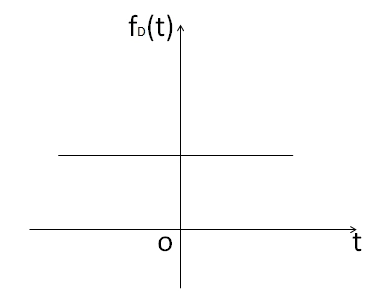

那么这些直流分量并不是我们希望得到的东西，那么它们是如何产生的呢？

实际上，信号都不是绝对的交流或直流， 例如直流电源的输出中总是在稳定的直流中包含一些波动，这些波动的成分就称为：交流分量。而稳定的成分就称为：直流分量。如果你懂得傅立叶变换，就更容易理解了。即对一个信号进行傅立叶分析，频率等于0的部分对应的幅值就是直流分量，其余的就是交流分量。

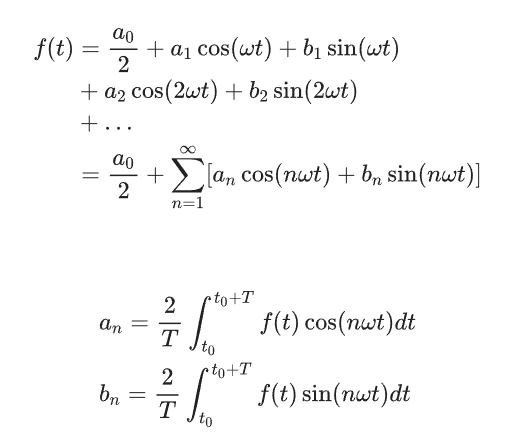

在电子学中，傅里叶级数是一种频域分析工具，可以理解成一种复杂的周期波分解成直流项、基波（角频率为ω）和各次谐波（角频率为nω）的和，也就是级数中的各项。一般，随着n的增大，各次谐波的能量逐渐衰减，所以一般从级数中取前n项之和就可以很好接近原周期波形。这是傅里叶级数在电子学分析中的重要应用。

其中，最重要的一句是：在电子学中，傅里叶级数是一种频域分析工具，可以理解成一种复杂的周期波分解成直流项、基波（角频率为ω）和各次谐波（角频率为nω）的和，也就是级数中的各项。

而直流项就是信号的直流分量。

在雷达中信号产生直流分量的原因主要有两种：

**（1）电路器件因素**

两个不同频率的高频电压作用于非线性器件时， 经非线性变换，电流中包含直流分量、基波、谐波、和频、差频分量等。

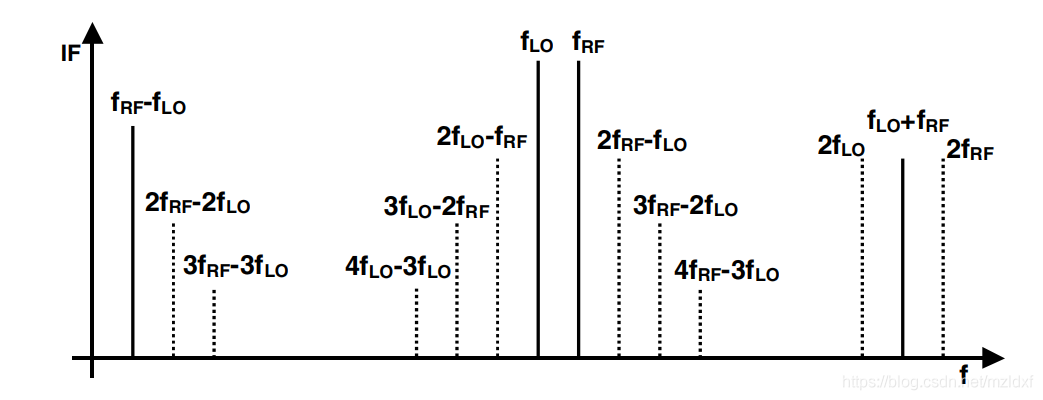

其中，差频分量才是混频所需要的中频成分，通过中频带通滤波器把其它不需要的频率分量滤掉，取出差频分量完成混频。ADC的采样的信号已经是经过带通滤波的，但是还是存在直流，因为直接耦合方式有缺点。采用直接耦合方式使各级之间的直流通路相连，因而静态工作点相互影响，有零点漂移现象。

另外，在温度变化条件下电路元件会产生温度漂移（温漂），在一定条件下需要考虑平衡补偿或者校准，实际上零中频接收机本身的难点之一就是直流均衡问题，这将会影响系统的动态范围。

**（2）收发天线隔离度不够好**

可以理解为产生了反射泄漏或者近距离回波。

如下图所示，是对128个chirp，每个chirp128个采样点的一帧雷达回波信号做距离维度的FFT得到的谱图。可以看到，在距离门号等于0的位置，具有很高的峰值（能量）。

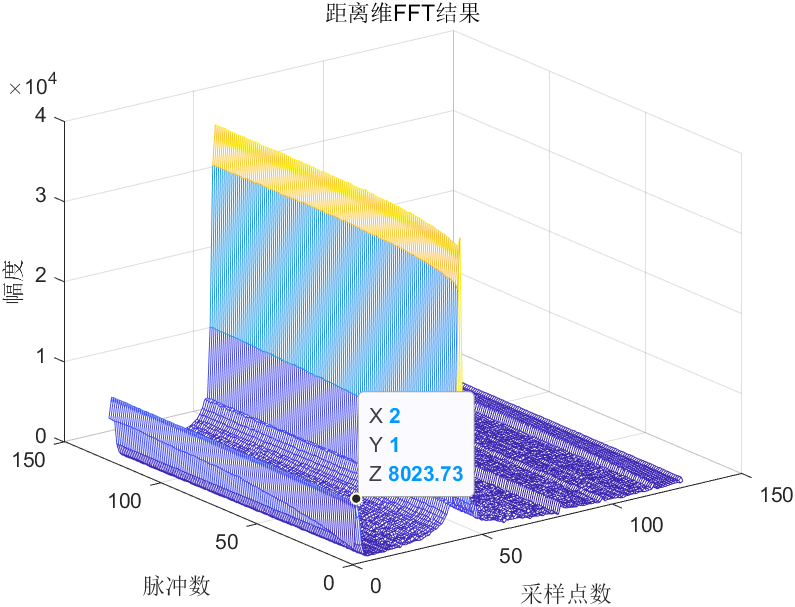

如果我们不关心距离为0（接近0），或者速度为零的目标，那我们最好能够将它们抑制掉，以便于我们方便后续的处理。

## **2. 均值相消**

关于速度维度上直流分量去除的问题，其实就是静态杂波滤除问题，在之前的文章中我们已经采用了相量均值相消算法，其实本质上讲相量均值相消算法就是一种去直流方法。

 首先对所有接收脉冲求平均得出参考接收脉冲，接着利用每一束接收脉冲减去参考接收脉冲就可以得到目标回波信号，参考接收脉冲的表达式为：


$$C[m]=\frac{1}{N}\sum_{i=1}^{N}R[m,i]$$


其中，m为快时间维（距离维）采样点，i为慢时间维（速度维）时间采样点，相量均值相消算法的公式为：


$$R[m,n]=R[m,n]-C[m]$$


 如下图所示，是相量均值相消算法的效果，信号的直流分量得到了一定程度的抑制，但整体抑制效果没有MTI那么明显。相量均值相消算法最优的特点是对目标的幅度没有削弱作用，但其背景噪声比较干净，同时对微多普勒的信息保留的比较完整，完全让目标保持了较高的信噪比。

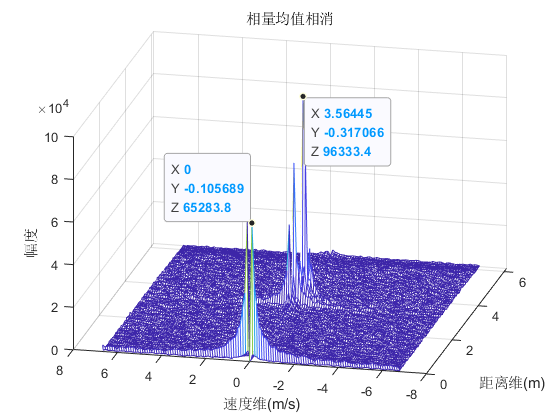

上图在距离维度上还是存在较强的距离维直流分量，因此本文采用同样的方法去除。D FFT和2D FFT的效果如下：

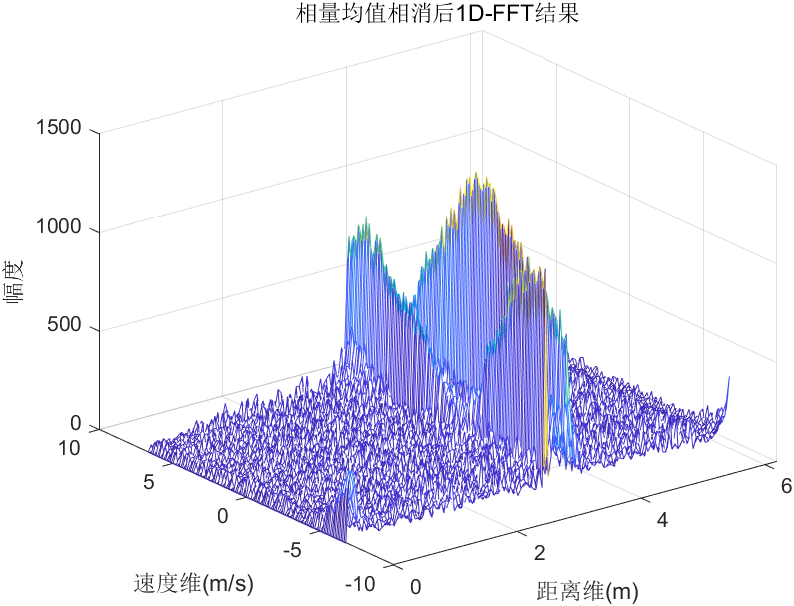

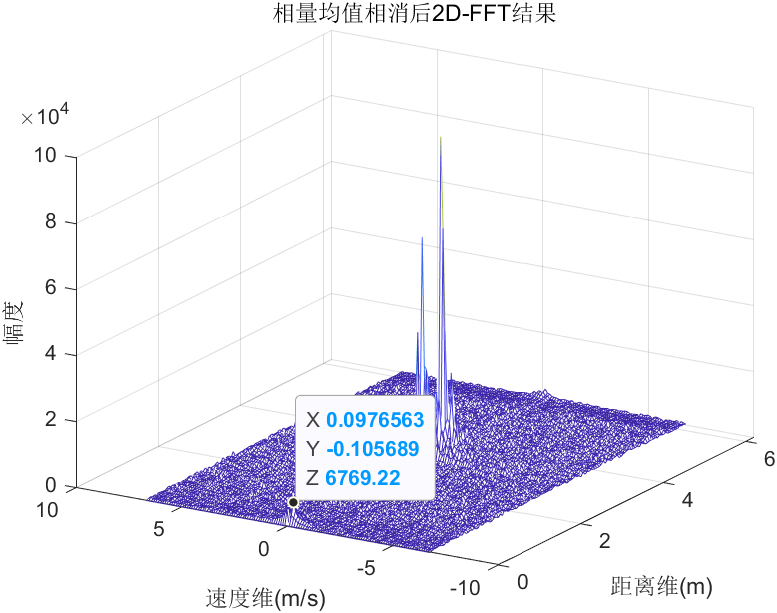

扣零法的效果如下所示，通过比较可以发现，其实两种方法得到的效果都差不多的，没有什么太大区别，本质上讲都是一样的。对于均值法是通过消除直流后再解算，而扣零法是把直流分量显现出来再一次性去除。

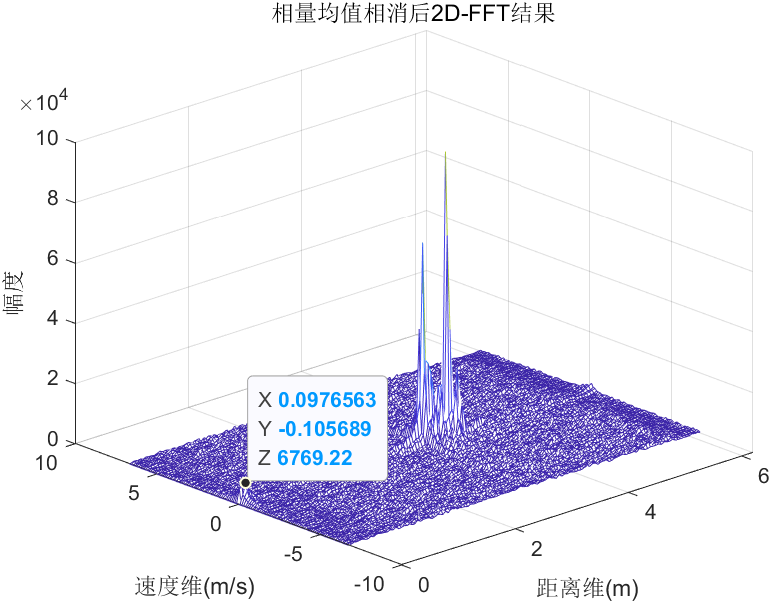

## 3.matlab仿真

%% 直流分量抑制 平均法（均值相消法）
%% 调皮的连续波 公众号
%% 调皮哥
%% 邮箱：tiaopige@qq.com
clc;
close all;
clear all;
%% 
%% 雷达参数
Tx_Number = 2;               %发射天线
Rx_Number = 4;               %接收天线
Range_Number = 128;          %距离点数（每个脉冲128个点）
Doppler_Number = 128;        %多普勒通道数(总共128个重复脉冲数)
global Params;
Params.NChirp = Doppler_Number;               %1帧数据的chirp个数
Params.NChan =  Rx_Number;                    %RxAn数,ADC通道数
Params.NSample = Range_Number;                %每个chirp ADC采样数
Params.Fs = 2.5e6;                           %采样频率
Params.c = 3.0e8;                     %光速
Params.startFreq = 77e9;              %起始频率 
Params.freqSlope = 60e12;             %chirp的斜率
Params.bandwidth = 3.072e9;           %真实带宽
Params.lambda=Params.c/Params.startFreq;    %雷达信号波长
Params.Tc = 144e-6;                         %chirp周期
global FFT2_mag;

%% 坐标计算
[X,Y] = meshgrid(Params.c*(0:Params.NSample-1)*Params.Fs/2/Params.freqSlope/Params.NSample, ...
    (-Params.NChirp/2:Params.NChirp/2 - 1)*Params.lambda/Params.Tc/Params.NChirp/2);   

%% 距离时域信号直流分量去除
load ReIm_Data_All.mat ;
fft1d_jingtai = zeros(Doppler_Number,Range_Number,Tx_Number*Rx_Number);
for n=1:Tx_Number*Rx_Number
    avg = sum(ReIm_Data_All(:,:,n),2)/Range_Number;
    for chirp=1:Range_Number
        fft1d_jingtai(:,chirp,n) = ReIm_Data_All(:,chirp,n)-avg;
    end
end

%% 1D FFT
fft1d= zeros(Doppler_Number,Range_Number,Tx_Number*Rx_Number);
for qq =1:Tx_Number*Rx_Number
    for chirp_fft=1:Doppler_Number 
        fft1d(chirp_fft,:,qq) = fft((fft1d_jingtai(chirp_fft,:,qq)));
    end
end
FFT1_mag=abs(fft1d(:,:,1));
figure();
mesh(FFT1_mag);
xlabel('采样点数');ylabel('脉冲数');zlabel('幅度');
title('距离维FFT结果');

%% 静态杂波滤除 速度维度的直流分量去除
fft1d_jingtai = zeros(Doppler_Number,Range_Number,Tx_Number*Rx_Number);
for n=1:Tx_Number*Rx_Number
    avg = sum(fft1d(:,:,n))/Doppler_Number;

    for chirp=1:Doppler_Number
        fft1d_jingtai(chirp,:,n) = fft1d(chirp,:,n)-avg;
    end
end
fft1d =fft1d_jingtai;
FFT1_mag=(abs(fft1d(:,:,1)));
figure();
mesh(X,Y,FFT1_mag);
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('相量均值相消后1D-FFT结果');


%% 2D FFT 
fft2d= zeros(Doppler_Number,Range_Number,Tx_Number*Rx_Number);
for kk=1:Tx_Number*Rx_Number
    for chirp_fft=1:Range_Number 
         fft2d(:,chirp_fft,kk) =fftshift( fft((fft1d(:,chirp_fft,kk))));  
    end
end
FFT2_mag=(abs(fft2d(:,:,1)));
figure();
mesh(X,Y,FFT2_mag);
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('相量均值相消后2D-FFT结果');

# 圆拟合算法去除雷达信号中的直流分量

## 1.圆拟合

简单的说，就是给你一堆离散的点，然后根据这些离散点的特点，拟合出一个圆，思想和最小二乘法线性拟合相似，模型如下图所示。

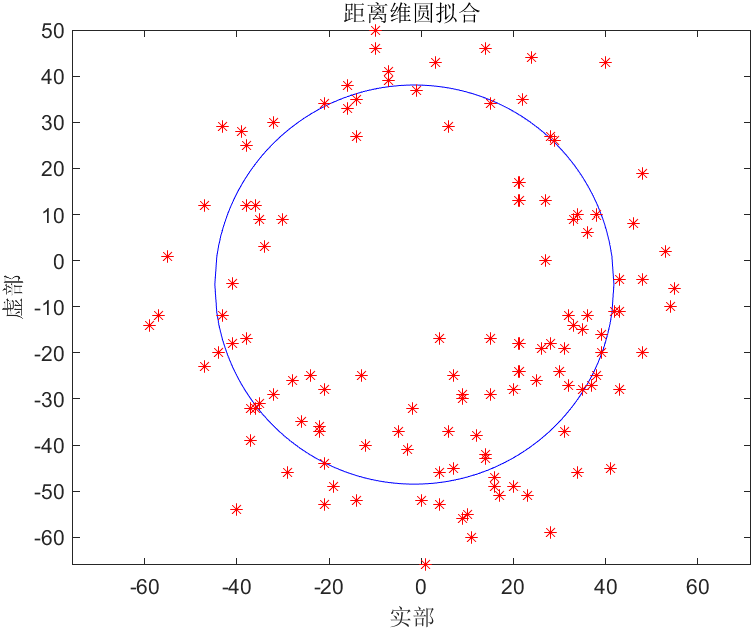

## 2.为什么可以采用圆拟合？

为什么用圆拟合算法就能够消除静态杂波干扰（直流分量）呢？这个问题是本文的核心问题，只有理解了这个才能明白圆拟合算法的本质。

我们知道，雷达回波信号经过正交采样后得到IQ复信号，时域IQ信号在复平面上的分布是随着采样点的幅度和相位散落在复平面上，如果不存在直流分量，那么离散点的是以零点为圆心，以幅度为半径，以随时间变化的相位为角度，呈圆弧分布。

如果受到静态物体产生的杂波干扰，由于信号存在直流分量，所以估计的相位随时间演变的幅值往往小于真实值，且杂波信号强度越大，偏差值越大，体现在图形中，就如下图所示，A1就是直流分量的幅度，可见A0因为受到直流分量的干扰，圆心偏离零点很远。

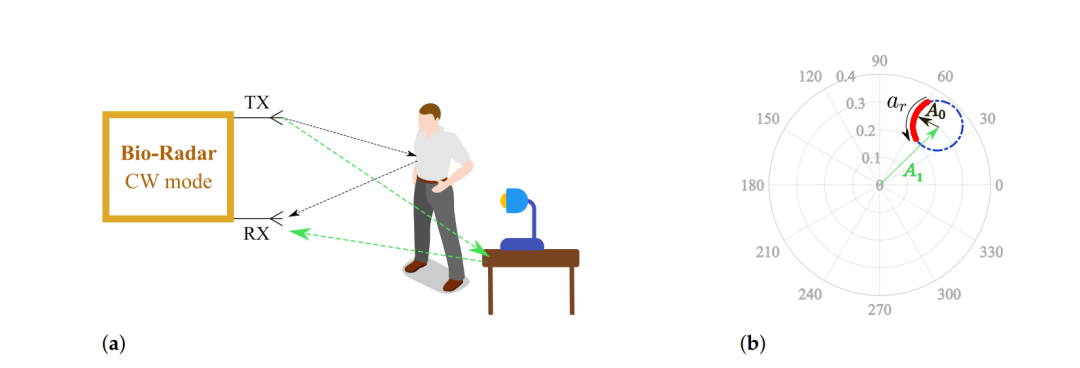

因此从信号处理的角度解决实际应用中静态杂波的干扰问题，因此可以利用信号后处理方法去补偿、校正相位时间序列的估计偏差，即消除A1的幅度，使得A0的圆心重回零点。

关于这部分内容的深刻理解，考虑到文章篇幅和时间关系，我暂时不做深入分析，下一篇文章会详细从底层解释，建议读者先反复深入理解傅里叶变换、复信号平面、直流和交流信号、向量叠加等内容。

## **3.雷达信号处理圆拟合算法步骤**

如果你了解了上面的原理后，其实算法程序编写起来很简单，步骤如下：

（1）找到当前离散点在复平面上的分布

（2）对这些点进行圆拟合操作

（3）根据拟合后的圆，补偿偏移

（4）根据补偿后的相位和幅度，得到新的离散点。

## **4.圆拟合数据说明与处理结果**

`MATLAB版本：2021a`

`操作系统：Win10`

`数据格式：脉冲数``*采样点数=128*``128的时域信号，是两个目标在3米附近相向而行。`

圆拟合采用最小二乘法实现。

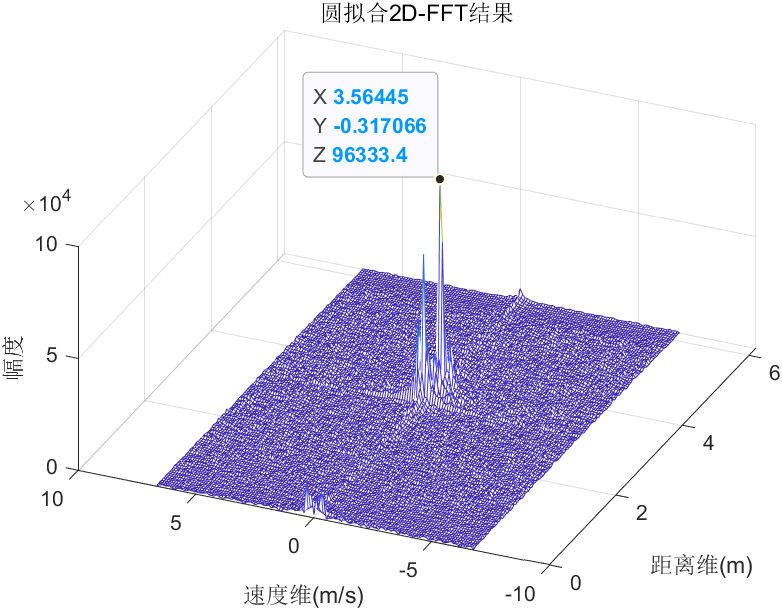

## **5.处理效果对比与分析**

说实话，其实效果一般，比起均值相消算法，圆拟合其实效果并不那么好，首先在距离维上的直流分量去除还有少量部分存在，速度维上也有少量直流分量（零速通道）没有消除，如下图所示。

总体看起来效果还能接受，不过就是计算量很大，不利于工程师实现。

## **6.程序分析**

**（1）雷达参数设置部分**

主要是根据采集目标信号时所设置的参数，各位读者可以根据自己的参数修改。建议初学者不要将采样点数和脉冲数设置为一样的，便于调试。

clc;
close all;
clear all;
%% 雷达参数
Tx_Number = 2;               %发射天线
Rx_Number = 4;               %接收天线
Range_Number = 128;          %距离点数（每个脉冲128个点）
Doppler_Number = 128;        %多普勒通道数(总共128个重复脉冲数)
global Params;
Params.NChirp = Doppler_Number;               %1帧数据的chirp个数
Params.NChan =  Rx_Number;                    %RxAn数,ADC通道数
Params.NSample = Range_Number;                %每个chirp ADC采样数
Params.Fs = 2.5e6;                           %采样频率
Params.c = 3.0e8;                     %光速
Params.startFreq = 77e9;              %起始频率 
Params.freqSlope = 60e12;             %chirp的斜率
Params.bandwidth = 3.072e9;           %真实带宽
Params.lambda=Params.c/Params.startFreq;    %雷达信号波长
Params.Tc = 144e-6;                         %chirp周期
global FFT2_mag;

**（2）坐标计算**

这部分就是根据公式计算绘制图形的坐标，挺简单的，根据雷达测距测速的原理公式就能够明白了。

%% 坐标计算
[X,Y] = meshgrid(Params.c*(0:Params.NSample-1)*Params.Fs/2/Params.freqSlope/Params.NSample, ...
    (-Params.NChirp/2:Params.NChirp/2 - 1)*Params.lambda/Params.Tc/Params.NChirp/2);

**（3）距离维直流分量去除**

首先load加载原始数据，赋值给`fft1d_before`变量，然后建立两个会用到的空数组。

load ReIm_Data_All_circ.mat ;
fft1d_before=ReIm_Data_All;
ai=zeros(Range_Number,Doppler_Number);
data=zeros(Range_Number,Doppler_Number,Tx_Number*Rx_Number);

距离维圆拟合程序如下，其实是同时对8个天线进行拟合，因此解算的速度会慢一些，其中程序有绘图的部分我给注释了，读者可以在自己调试时打开并观察结果。拟合的算法采用的是最小二乘法，其原理请各位读者自行研究。


for antenna=1:Tx_Number*Rx_Number
    for Range=1:Range_Number
        %1.估计每个扫频周期时间内的基带复信号中频信号的幅值
        AmR(Range,:)=fft1d_before(Range,:,antenna);

        %2.幅值时间序列和已知的初始相位时间序列得到复平面上的离散点       
%         figure(2);
%         plot(fft1d(:,doppler,1),'o');
%         title([num2str(doppler)]);

        %3.一个距离门上的所有多普勒点进行圆拟合
        xdataR=real(AmR(Range,:));
        ydataR=imag(AmR(Range,:));

        %最小二乘法拟合
        k0 = ones(1,3);
        F = @(k)(xdataR-k(1)).^2+(ydataR-k(2)).^2-k(3)^2;
        [k,resnorm] = lsqnonlin(F,k0);

        %k(1)是圆心的x坐标
        %k(2)是圆心的y坐标
        %k(3)的绝对值是圆的半径

%         r0 = [k(1),k(2)];
%         R = abs(k(3));
%         xx = k(1)-R:0.01*R:k(1)+R;
%         y1_h = sqrt(R.^2 - (xx - r0(1)).^2) + r0(2);
%         y2_h = -sqrt(R.^2 - (xx - r0(1)).^2) + r0(2);
%         figure(1);
%         plot(xx,y1_h,'b')
%         hold on
%         plot(xx,y2_h','b')
%         plot(xdata,ydata,'*r')
%         title('距离维圆拟合');
%         xlabel('实部');
%         ylabel('虚部');
%         axis equal %axis square

        %4.修正补偿
        %获取拟合圆的圆心
        x=k(1);
        y=k(2);

        %将圆心移到零点（0，0）
        xdataR=xdataR-x;
        ydataR=ydataR-y;

        %5.得到新的点的时间序列相位
        dataR(Range,:,antenna)=complex(xdataR,ydataR);
        hold off;
    end
 end


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria d

（4）速度维直流分量去除

速度维和距离维的算法一样，其实就是采用两次圆拟合运算，这里为了方便理解，我分开做计算，读者可以优化这个程序步骤，使得算法运算更加有效率。

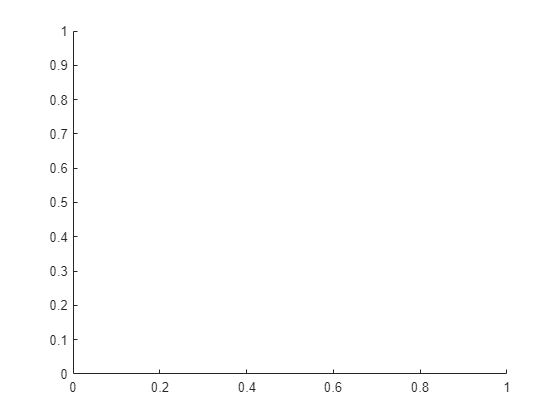


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria d

 %% 速度维 圆拟合
AmV=zeros(Range_Number,Doppler_Number);
dataV=zeros(Range_Number,Doppler_Number,Tx_Number*Rx_Number);
 for antenna=1:Tx_Number*Rx_Number
    for doppler=1:Doppler_Number
        %1.估计每个扫频周期时间内的基带复信号中频信号的幅值
        AmV(:,doppler)=dataR(:,doppler,antenna);

        %2.幅值时间序列和已知的初始相位时间序列得到复平面上的离散点       
%         figure(2);
%         plot(fft1d(:,doppler,1),'o');
%         title([num2str(doppler)]);

        %3.一个距离门上的所有多普勒点进行圆拟合
        xdataV=real(AmV(:,doppler));
        ydataV=imag(AmV(:,doppler));

        %最小二乘法拟合
        k0 = ones(1,3);
        F = @(k)(xdataV-k(1)).^2+(ydataV-k(2)).^2-k(3)^2;
        [k,resnorm] = lsqnonlin(F,k0);

        %k(1)是圆心的x坐标
        %k(2)是圆心的y坐标
        %k(3)的绝对值是圆的半径

%         r0 = [k(1),k(2)];
%         R = abs(k(3));
%         xx = k(1)-R:0.01*R:k(1)+R;
%         y1_h = sqrt(R.^2 - (xx - r0(1)).^2) + r0(2);
%         y2_h = -sqrt(R.^2 - (xx - r0(1)).^2) + r0(2);
%         figure(1);
%         plot(xx,y1_h,'b')
%         hold on
%         plot(xx,y2_h','b')
%         plot(xdata,ydata,'*r')
%         axis equal %axis square

        %4.修正补偿
        %获取拟合圆的圆心
        x=k(1);
        y=k(2);

        %将圆心移到零点（0，0）
        xdataV=xdataV-x;
        ydataV=ydataV-y;

        %5.得到新的点的时间序列相位
        dataV(:,doppler,antenna)=complex(xdataV,ydataV);
        hold off;
    end
 end

**（5）距离维和速度维FFT**

在这里我们其实清楚地知道，两次圆拟合算法都是在FFT运算之前做的。本程序还有很多图形暂时注释，读者可以自行画出分析，比如拟合前、拟合后的图形以及信号波形等，我个人觉得读者应该有较高的编程能力，这些都不是困难的事情，因此不再繁琐列出。

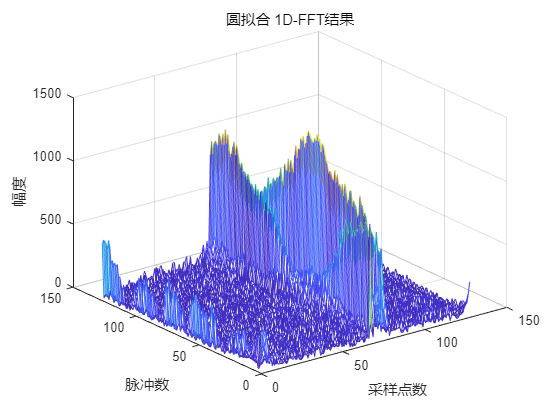

 
%% 1D FFT
fft1d= zeros(Range_Number,Doppler_Number,Tx_Number*Rx_Number);
for antenna =1:Tx_Number*Rx_Number
    for Range=1:Range_Number 
        fft1d(Range,:,antenna) = fft((dataV(Range,:,antenna)));
    end
end

FFT1_mag=abs(fft1d(:,:,1));
figure();
mesh(FFT1_mag);
xlabel('采样点数');ylabel('脉冲数');zlabel('幅度');
title('圆拟合 1D-FFT结果');

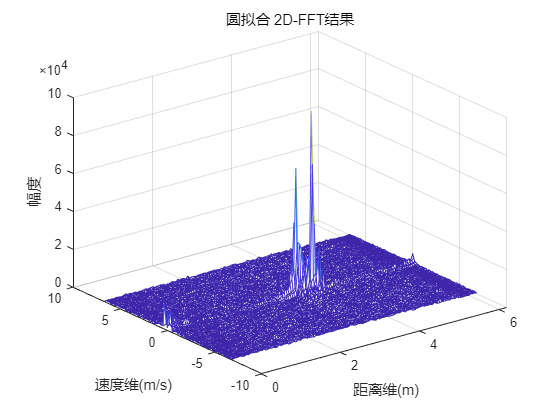


%% 2D-FFT 
fft2d= zeros(Range_Number,Doppler_Number,Tx_Number*Rx_Number);
for antenna=1:Tx_Number*Rx_Number
    for doppler=1:Doppler_Number 
         fft2d(:,doppler,antenna) =fftshift( fft((fft1d(:,doppler,antenna))));  
    end
end
FFT2_mag=(abs(fft2d(:,:,1)));
figure();
mesh(X,Y,FFT2_mag);
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('圆拟合 2D-FFT结果');